n = length(x);
opts = optimoptions('ga', 'Display', 'iter');

beq_values = [24, 21, 18, 15, 12];
Aeq = ones(1, n);

problem2_results = struct([]);

for i = 1:numel(beq_values)
    beq = beq_values(i);

    fprintf('\n========== beq = %g, sum(t) = %g ==========\n', beq, beq);

    t_opt = ga(@(t) objFun(t, classicload, classicwind, classicsun, fenshijijia), ...
               n, [], [], Aeq, beq, zeros(n,1), ones(n,1), [], 1:n, opts);
    t_opt = t_opt(:);
    J_min = objFun(t_opt, classicload, classicwind, classicsun, fenshijijia);
    fprintf('最小目标值 J = %.6g\n', J_min);
    disp('最优 t 向量：'); disp(t_opt);

    problem2_nh3load = t_opt*20.75*2;
    problem2_load = classicload*6 + problem2_nh3load;
    problem2_generate = classicwind*40 + classicsun*64;
    problem2_buy = problem2_load - problem2_generate;
    problem2_sell = problem2_buy;
    problem2_buy(problem2_buy<0) = 0;
    problem2_sell(problem2_sell>0) = 0;
    problem2_buycost = sum(problem2_buy .* fenshijijia);
    problem2_dayload = sum(problem2_load);
    problem2_daygenerate = sum(problem2_generate);
    problem2_daybuy = sum(problem2_buy);
    problem2_daysell = abs(sum(problem2_sell));
    problem2_xnyzf = (problem2_dayload-problem2_daysell-problem2_daybuy)/problem2_daygenerate;
    problem2_zydl = (problem2_daygenerate-problem2_daysell)/problem2_dayload;
    problem2_xnysw = problem2_daysell/problem2_daygenerate;
    fprintf('新能源自发自用电量占总可用发电量比例 = %.6g\n', problem2_xnyzf);
    fprintf('总用电量中绿电占比 = %.6g\n', problem2_zydl);
    fprintf('新能源上网电量比例 = %.6g\n', problem2_xnysw);

    problem2_results(i).beq = beq;
    problem2_results(i).t_opt = t_opt;
    problem2_results(i).J_min = J_min;
    problem2_results(i).nh3load = problem2_nh3load;
    problem2_results(i).load = problem2_load;
    problem2_results(i).generate = problem2_generate;
    problem2_results(i).buy = problem2_buy;
    problem2_results(i).sell = problem2_sell;
    problem2_results(i).buycost = problem2_buycost;
    problem2_results(i).dayload = problem2_dayload;
    problem2_results(i).daygenerate = problem2_daygenerate;
    problem2_results(i).daybuy = problem2_daybuy;
    problem2_results(i).daysell = problem2_daysell;
    problem2_results(i).xnyzf = problem2_xnyzf;
    problem2_results(i).zydl = problem2_zydl;
    problem2_results(i).xnysw = problem2_xnysw;
end


========== beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6265            6265        0
    2                3            6265            6265        1
    3                4            6265            6265        2
    4                5            6265            6265        3
    5                6            6265            6265        4
    6                7            6265            6265        5
    7                8            6265            6265        6
    8                9            6265            6265        7
    9               10            6265            6265        8
   10               11            6265            6265        9
   11               12       

最小目标值 J = 6264.8


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.865174


总用电量中绿电占比 = 0.532561


新能源上网电量比例 = 0.0674129



========== beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              158            6133            6196        0
    2              238            6133            6197        1
    3              318            6133            6197        2
    4              402            6110            6194        0
    5              481            6110            6194        1
    6              563            6110            6194        2
    7              642            5951            6195        0
    8              724            5951            6189        1
    9              805            5899            6183        0
   10              886            5899            6176        1
   11              965       

最小目标值 J = 5762.47


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.719558


总用电量中绿电占比 = 0.556555


新能源上网电量比例 = 0.140221



========== beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            5723            6071        0
    2              293            5545            6031        0
    3              388            5453            6025        0
    4              483            5453            6019        1
    5              578            5423            5997        0
    6              673            5421            5974        0
    7              768            5421            5990        1
    8              863            5421            5971        2
    9              958            5392            5962        0
   10             1053            5392            5972        1
   11             1148       

最小目标值 J = 4997.99


最优 t 向量：
     0
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.654217


总用电量中绿电占比 = 0.617933


新能源上网电量比例 = 0.172891



========== beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4314            5582        0
    2              295            4314            5525        1
    3              390            4314            5503        2
    4              485            4314            5389        3
    5              580            4314            5364        4
    6              675            4244            5292        0
    7              770            4244            5336        1
    8              865            4244            5324        2
    9              960            4244            5312        3
   10             1055            4244            5271        4
   11             1150       

最小目标值 J = 4017.6


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.509777


总用电量中绿电占比 = 0.666749


新能源上网电量比例 = 0.245111



========== beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3842            4749        0
    2              295            3842            4634        1
    3              390            3812            4592        0
    4              485            3761            4565        0
    5              580            3761            4530        1
    6              675            3761            4670        2
    7              770            3647            4590        0
    8              865            3647            4610        1
    9              960            3628            4545        0
   10             1055            3628            4527        1
   11             1150       

最小目标值 J = 3283


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.105042


总用电量中绿电占比 = 0.596753


新能源上网电量比例 = 0.447479



function J = objFun(t, classicload, classicwind, classicsun, fenshijijia)
    t = t(:);
    problem2_nh3load = t*20.75*2;
    problem2_load = classicload*6 + problem2_nh3load;
    problem2_generate = classicwind*40 + classicsun*64;
    problem2_buy = problem2_load - problem2_generate;
    problem2_sell = problem2_buy;
    problem2_buy(problem2_buy<0) = 0;
    problem2_sell(problem2_sell>0) = 0;
    problem2_buycost = sum(problem2_buy .* fenshijijia);
    problem2_sellcost = sum(problem2_sell*377.9);
    problem2_cost =   problem2_sellcost + problem2_buycost ...
                  + 0.75*2*sum(t)*2 ...
                  + 1.5*2*1000*0.2*60000/365/30 ...
                  + 10*2*sum(t)*100 ...
                  + 10*2*sum(t)*150 ...
                  + sum(classicsun)*64*1000*0.12 ...
                  + sum(classicwind)*40*1000*0.15;
    J = problem2_cost / (sum(t)*3);
end

wind_vectors = {wind1(:), wind2(:), wind3(:), wind4(:), wind5(:), wind6(:)};
wind_names = {'wind1', 'wind2', 'wind3', 'wind4', 'wind5', 'wind6'};
sun_vectors = {sun1(:), sun2(:), sun3(:), sun4(:)};
sun_names = {'sun1', 'sun2', 'sun3', 'sun4'};

classicload = classicload(:);
fenshijijia = fenshijijia(:);
n = numel(wind_vectors{1});


opts = optimoptions('ga', 'Display', 'iter');

% 分别在以下约束下运行优化：sum(t) = beq
beq_values = [24, 21, 18, 15, 12];
Aeq = ones(1, n);

problem2_results = struct([]);
result_idx = 0;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    wind_name = wind_names{wind_idx};

    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};
        sun_name = sun_names{sun_idx};

        fprintf('\n\n==================== 情况 %02d：%s + %s ====================\n', ...
                (wind_idx - 1)*numel(sun_vectors) + sun_idx, wind_name, sun_name);

        for beq_idx = 1:numel(beq_values)
            beq = beq_values(beq_idx);

            fprintf('\n========== %s + %s, beq = %g, sum(t) = %g ==========\n', ...
                    wind_name, sun_name, beq, beq);

            t_opt = ga(@(t) objFun(t, classicload, wind, sun, fenshijijia), ...
                       n, [], [], Aeq, beq, zeros(n,1), ones(n,1), [], 1:n, opts);
            t_opt = t_opt(:);
            J_min = objFun(t_opt, classicload, wind, sun, fenshijijia);
            fprintf('最小目标值 J = %.6g\n', J_min);
            disp('最优 t 向量：'); disp(t_opt);

            metrics = calcProblem2Metrics(t_opt, classicload, wind, sun, fenshijijia);
                                         

            problem2_nh3load = metrics.nh3load;
            problem2_load = metrics.load;
            problem2_generate = metrics.generate;
            problem2_buy = metrics.buy;
            problem2_sell = metrics.sell;
            problem2_buycost = metrics.buycost;
            problem2_dayload = metrics.dayload;
            problem2_daygenerate = metrics.daygenerate;
            problem2_daybuy = metrics.daybuy;
            problem2_daysell = metrics.daysell;
            problem2_xnyzf = metrics.xnyzf;
            problem2_zydl = metrics.zydl;
            problem2_xnysw = metrics.xnysw;

            fprintf('新能源自发自用电量占总可用发电量比例 = %.6g\n', problem2_xnyzf);
            fprintf('总用电量中绿电占比 = %.6g\n', problem2_zydl);
            fprintf('新能源上网电量比例 = %.6g\n', problem2_xnysw);

            result_idx = result_idx + 1;
            problem2_results(result_idx).case_idx = result_idx;
            problem2_results(result_idx).wind_idx = wind_idx;
            problem2_results(result_idx).wind_name = wind_name;
            problem2_results(result_idx).sun_idx = sun_idx;
            problem2_results(result_idx).sun_name = sun_name;
            problem2_results(result_idx).beq = beq;
            problem2_results(result_idx).t_opt = t_opt;
            problem2_results(result_idx).J_min = J_min;
            problem2_results(result_idx).nh3load = problem2_nh3load;
            problem2_results(result_idx).load = problem2_load;
            problem2_results(result_idx).generate = problem2_generate;
            problem2_results(result_idx).buy = problem2_buy;
            problem2_results(result_idx).sell = problem2_sell;
            problem2_results(result_idx).buycost = problem2_buycost;
            problem2_results(result_idx).dayload = problem2_dayload;
            problem2_results(result_idx).daygenerate = problem2_daygenerate;
            problem2_results(result_idx).daybuy = problem2_daybuy;
            problem2_results(result_idx).daysell = problem2_daysell;
            problem2_results(result_idx).xnyzf = problem2_xnyzf;
            problem2_results(result_idx).zydl = problem2_zydl;
            problem2_results(result_idx).xnysw = problem2_xnysw;
        end
    end
end



==================== 情况 01：wind1 + sun1 ====================



========== wind1 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5430            5430        0
    2                3            5430            5430        1
    3                4            5430            5430        2
    4                5            5430            5430        3
    5                6            5430            5430        4
    6                7            5430            5430        5
    7                8            5430            5430        6
    8                9            5430            5430        7
    9               10            5430            5430        8
   10               11            5430            5430        9
   11               12       

最小目标值 J = 5430.08


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.644709


总用电量中绿电占比 = 0.592816


新能源上网电量比例 = 0.177646



========== wind1 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              159            5221            5252        0
    2              242            5221            5254        1
    3              325            5221            5254        2
    4              405            5221            5255        3
    5              488            5221            5254        4
    6              571            5221            5254        5
    7              651            5221            5255        6
    8              730            5074            5253        0
    9              815            5074            5252        1
   10              897            5058            5250        0
   11              978       

最小目标值 J = 4993.72


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.423112


总用电量中绿电占比 = 0.581448


新能源上网电量比例 = 0.288444



========== wind1 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4392            4951        0
    2              295            4392            4939        1
    3              390            4392            4911        2
    4              485            4371            4910        0
    5              580            4371            4910        1
    6              675            4371            4911        2
    7              770            4371            4902        0
    8              865            4313            4919        0
    9              960            4313            4905        1
   10             1055            4313            4868        2
   11             1150       

最小目标值 J = 3796.97


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.46689


总用电量中绿电占比 = 0.691715


新能源上网电量比例 = 0.266555



========== wind1 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3344            4346        0
    2              295            3344            4330        1
    3              390            3344            4297        2
    4              485            3323            4234        0
    5              580            3323            4204        1
    6              675            3323            4169        2
    7              770            3323            4217        3
    8              865            3323            4223        4
    9              960            3323            4173        5
   10             1055            3214            4134        0
   11             1150       

最小目标值 J = 3096.74


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.181494


总用电量中绿电占比 = 0.65866


新能源上网电量比例 = 0.409253



========== wind1 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2240            3309        0
    2              295            2240            3203        1
    3              390            2240            3134        2
    4              485            2240            3113        3
    5              580            2240            3092        4
    6              675            2240            3058        5
    7              770            2240            3080        6
    8              865            2240            3044        7
    9              960            2235            3083        0
   10             1055            2235            3078        1
   11             1150       

最小目标值 J = 2147.11


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     0
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.145379


总用电量中绿电占比 = 0.582599


新能源上网电量比例 = 0.572689




==================== 情况 02：wind1 + sun2 ====================



========== wind1 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6803            6803        0
    2                3            6803            6803        1
    3                4            6803            6803        2
    4                5            6803            6803        3
    5                6            6803            6803        4
    6                7            6803            6803        5
    7                8            6803            6803        6
    8                9            6803            6803        7
    9               10            6803            6803        8
   10               11            6803            6803        9
   11               12       

最小目标值 J = 6802.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.970389


总用电量中绿电占比 = 0.469144


新能源上网电量比例 = 0.0148055



========== wind1 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              150            6672            6788        0
    2              229            6611            6785        0
    3              308            6611            6783        1
    4              386            6611            6784        2
    5              469            6601            6779        0
    6              553            6601            6774        1
    7              636            6586            6779        0
    8              718            6586            6776        1
    9              801            6513            6774        0
   10              882            6502            6770        0
   11              966       

最小目标值 J = 6427.25


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.754278


总用电量中绿电占比 = 0.473472


新能源上网电量比例 = 0.122861



========== wind1 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            6006            6599        0
    2              293            6006            6594        1
    3              388            6006            6572        2
    4              483            5830            6530        0
    5              578            5830            6529        1
    6              673            5830            6543        2
    7              768            5830            6531        3
    8              863            5829            6536        0
    9              958            5829            6570        1
   10             1053            5775            6539        0
   11             1148       

最小目标值 J = 5632.42


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.668117


总用电量中绿电占比 = 0.519613


新能源上网电量比例 = 0.165941



========== wind1 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5124            6290        0
    2              295            5124            6220        1
    3              390            5043            6148        0
    4              485            5043            6134        1
    5              580            5043            6096        2
    6              675            5043            6071        3
    7              770            5043            6006        4
    8              865            5043            6046        5
    9              960            5043            5978        6
   10             1055            5043            5911        7
   11             1150       

最小目标值 J = 4888.7


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.526482


总用电量中绿电占比 = 0.562141


新能源上网电量比例 = 0.236759



========== wind1 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4646            5647        0
    2              295            4615            5570        0
    3              390            4615            5494        1
    4              485            4615            5443        2
    5              580            4529            5359        0
    6              675            4529            5321        1
    7              770            4529            5426        2
    8              865            4529            5386        3
    9              960            4529            5296        4
   10             1055            4421            5298        0
   11             1150       

最小目标值 J = 4118.61


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.177327


总用电量中绿电占比 = 0.530172


新能源上网电量比例 = 0.411337




==================== 情况 03：wind1 + sun3 ====================



========== wind1 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8163            8163        0
    2                3            8163            8163        1
    3                4            8163            8163        2
    4                5            8163            8163        3
    5                6            8163            8163        4
    6                7            8163            8163        5
    7                8            8163            8163        6
    8                9            8163            8163        7
    9               10            8163            8163        8
   10               11            8163            8163        9
   11               12       

最小目标值 J = 8163.38


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.319332


新能源上网电量比例 = 0



========== wind1 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              148            7904            8286        0
    2              230            7904            8284        1
    3              311            7904            8278        2
    4              393            7904            8276        3
    5              474            7904            8280        4
    6              559            7904            8275        5
    7              644            7904            8275        6
    8              727            7904            8269        7
    9              810            7904            8286        8
   10              894            7886            8274        0
   11              975       

最小目标值 J = 7747.66


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.787118


总用电量中绿电占比 = 0.32345


新能源上网电量比例 = 0.106441



========== wind1 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              195            7737            8241        0
    2              288            7737            8232        1
    3              383            7737            8195        2
    4              478            7557            8178        0
    5              573            7557            8191        1
    6              668            7557            8191        2
    7              763            7557            8155        3
    8              858            7557            8153        4
    9              953            7381            8117        0
   10             1048            7365            8146        0
   11             1143       

最小目标值 J = 7206.52


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.564324


总用电量中绿电占比 = 0.326766


新能源上网电量比例 = 0.217838



========== wind1 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7023            7933        0
    2              295            6786            7901        0
    3              390            6786            7890        1
    4              485            6786            7780        2
    5              580            6786            7726        3
    6              675            6786            7722        4
    7              770            6786            7644        5
    8              865            6786            7603        6
    9              960            6569            7600        0
   10             1055            6569            7630        1
   11             1150       

最小目标值 J = 6569.28


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.361348


总用电量中绿电占比 = 0.336187


新能源上网电量比例 = 0.319326



========== wind1 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6527            7541        0
    2              295            6527            7450        1
    3              390            6527            7460        2
    4              485            6527            7490        3
    5              580            6527            7433        4
    6              675            6527            7477        5
    7              770            6527            7490        6
    8              865            6427            7385        0
    9              960            6367            7423        0
   10             1055            6367            7359        1
   11             1150       

最小目标值 J = 5923.5


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.226575


总用电量中绿电占比 = 0.370401


新能源上网电量比例 = 0.386712




==================== 情况 04：wind1 + sun4 ====================



========== wind1 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8712            8712        0
    2                3            8712            8712        1
    3                4            8712            8712        2
    4                5            8712            8712        3
    5                6            8712            8712        4
    6                7            8712            8712        5
    7                8            8712            8712        6
    8                9            8712            8712        7
    9               10            8712            8712        8
   10               11            8712            8712        9
   11               12       

最小目标值 J = 8711.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.258161


新能源上网电量比例 = 0



========== wind1 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              158            8514            8895        0
    2              243            8398            8887        0
    3              328            8398            8875        1
    4              410            8275            8877        0
    5              492            8275            8896        1
    6              571            8275            8889        2
    7              655            8275            8873        3
    8              738            8275            8873        4
    9              819            8275            8853        5
   10              900            8275            8863        6
   11              984       

最小目标值 J = 8274.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.845326


总用电量中绿电占比 = 0.270007


新能源上网电量比例 = 0.0773368



========== wind1 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            8084            8848        0
    2              291            8084            8772        1
    3              385            8084            8755        2
    4              480            8035            8686        0
    5              575            7973            8725        0
    6              670            7944            8704        0
    7              765            7944            8715        1
    8              860            7944            8663        2
    9              955            7944            8674        3
   10             1050            7831            8679        0
   11             1145       

最小目标值 J = 7619.87


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.757655


总用电量中绿电占比 = 0.29682


新能源上网电量比例 = 0.121173



========== wind1 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7564            8540        0
    2              295            7564            8515        1
    3              390            7564            8485        2
    4              485            7564            8502        3
    5              580            7564            8429        4
    6              675            7564            8386        5
    7              770            7564            8336        6
    8              865            7412            8393        0
    9              960            7412            8393        1
   10             1055            7412            8372        2
   11             1150       

最小目标值 J = 7044.19


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.533771


总用电量中绿电占比 = 0.306211


新能源上网电量比例 = 0.233115



========== wind1 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7344            8377        0
    2              295            7173            8299        0
    3              390            7164            8186        0
    4              485            7164            8219        1
    5              580            7090            8154        0
    6              675            7090            8133        1
    7              770            7090            8229        2
    8              865            7090            8222        3
    9              960            7090            8182        4
   10             1055            7090            8201        5
   11             1150       

最小目标值 J = 6396.46


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.408732


总用电量中绿电占比 = 0.343918


新能源上网电量比例 = 0.295634




==================== 情况 05：wind2 + sun1 ====================



========== wind2 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5836            5836        0
    2                3            5836            5836        1
    3                4            5836            5836        2
    4                5            5836            5836        3
    5                6            5836            5836        4
    6                7            5836            5836        5
    7                8            5836            5836        6
    8                9            5836            5836        7
    9               10            5836            5836        8
   10               11            5836            5836        9
   11               12       

最小目标值 J = 5835.93


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.727997


总用电量中绿电占比 = 0.538735


新能源上网电量比例 = 0.136002



========== wind2 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              159            5629            5712        0
    2              243            5629            5711        1
    3              322            5629            5710        2
    4              404            5629            5712        3
    5              482            5629            5714        4
    6              565            5629            5708        5
    7              646            5545            5707        0
    8              728            5513            5705        0
    9              806            5513            5704        1
   10              885            5483            5698        0
   11              965       

最小目标值 J = 5451.5


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.476397


总用电量中绿电占比 = 0.521767


新能源上网电量比例 = 0.261801



========== wind2 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            5166            5500        0
    2              292            5157            5480        0
    3              387            4880            5472        0
    4              482            4880            5461        1
    5              577            4880            5455        2
    6              672            4880            5430        3
    7              767            4650            5421        0
    8              862            4650            5421        1
    9              957            4650            5413        2
   10             1052            4650            5397        3
   11             1147       

最小目标值 J = 4235.58


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.587842


总用电量中绿电占比 = 0.647647


新能源上网电量比例 = 0.206079



========== wind2 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4236            5005        0
    2              295            4236            5019        1
    3              390            3965            4956        0
    4              485            3854            4849        0
    5              580            3854            4877        1
    6              675            3854            4889        2
    7              770            3854            4826        3
    8              865            3854            4818        4
    9              960            3854            4837        5
   10             1055            3744            4799        0
   11             1150       

最小目标值 J = 3613.35


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.26368


总用电量中绿电占比 = 0.609352


新能源上网电量比例 = 0.36816



========== wind2 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3256            4129        0
    2              295            3256            4120        1
    3              390            3254            4067        0
    4              485            3197            4102        0
    5              580            2952            3994        0
    6              675            2891            3947        0
    7              770            2891            3970        1
    8              865            2891            3859        2
    9              960            2891            3780        3
   10             1055            2891            3798        4
   11             1150       

最小目标值 J = 2769.65


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.103166


总用电量中绿电占比 = 0.528822


新能源上网电量比例 = 0.551583




==================== 情况 06：wind2 + sun2 ====================



========== wind2 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7366            7366        0
    2                3            7366            7366        1
    3                4            7366            7366        2
    4                5            7366            7366        3
    5                6            7366            7366        4
    6                7            7366            7366        5
    7                8            7366            7366        6
    8                9            7366            7366        7
    9               10            7366            7366        8
   10               11            7366            7366        9
   11               12       

最小目标值 J = 7365.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.378855


新能源上网电量比例 = 0



========== wind2 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              156            7097            7389        0
    2              240            7097            7391        1
    3              318            7097            7392        2
    4              400            7097            7386        3
    5              477            7097            7392        4
    6              559            7097            7391        5
    7              640            7097            7393        6
    8              721            7097            7390        7
    9              803            7097            7393        8
   10              882            7097            7403        9
   11              961       

最小目标值 J = 7048.97


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.904642


总用电量中绿电占比 = 0.408976


新能源上网电量比例 = 0.047679



========== wind2 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            6840            7311        0
    2              292            6832            7294        0
    3              387            6771            7265        0
    4              482            6700            7255        0
    5              577            6700            7232        1
    6              672            6700            7212        2
    7              767            6700            7200        3
    8              862            6531            7216        0
    9              957            6531            7231        1
   10             1052            6531            7204        2
   11             1147       

最小目标值 J = 6226.48


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.726405


总用电量中绿电占比 = 0.427844


新能源上网电量比例 = 0.136797



========== wind2 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6277            7072        0
    2              295            6226            7000        0
    3              390            6226            6985        1
    4              485            5853            6979        0
    5              580            5853            6888        1
    6              675            5853            6850        2
    7              770            5853            6900        3
    8              865            5853            6892        4
    9              960            5853            6876        5
   10             1055            5853            6822        6
   11             1150       

最小目标值 J = 5527.3


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.658303


总用电量中绿电占比 = 0.485855


新能源上网电量比例 = 0.170849



========== wind2 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5508            6528        0
    2              295            5508            6472        1
    3              390            5455            6374        0
    4              485            5080            6325        0
    5              580            5080            6269        1
    6              675            5080            6211        2
    7              770            5080            6333        3
    8              865            5080            6298        4
    9              960            5080            6283        5
   10             1055            4959            6255        0
   11             1150       

最小目标值 J = 4852.1


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.25607


总用电量中绿电占比 = 0.450011


新能源上网电量比例 = 0.371965




==================== 情况 07：wind2 + sun3 ====================



========== wind2 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8770            8770        0
    2                3            8770            8770        1
    3                4            8770            8770        2
    4                5            8770            8770        3
    5                6            8770            8770        4
    6                7            8770            8770        5
    7                8            8770            8770        6
    8                9            8770            8770        7
    9               10            8770            8770        8
   10               11            8770            8770        9
   11               12       

最小目标值 J = 8770.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.221993


新能源上网电量比例 = 0



========== wind2 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            8571            8960        0
    2              238            8571            8951        1
    3              320            8489            8952        0
    4              404            8482            8931        0
    5              484            8482            8959        1
    6              566            8482            8930        2
    7              651            8482            8927        3
    8              734            8482            8942        4
    9              817            8482            8930        5
   10              898            8482            8935        6
   11              980       

最小目标值 J = 8372.75


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.780635


总用电量中绿电占比 = 0.22404


新能源上网电量比例 = 0.109683



========== wind2 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            8256            8929        0
    2              292            8256            8936        1
    3              387            8256            8894        2
    4              482            8079            8862        0
    5              577            7928            8850        0
    6              672            7928            8819        1
    7              767            7928            8783        2
    8              862            7928            8787        3
    9              957            7928            8744        4
   10             1052            7928            8744        5
   11             1147       

最小目标值 J = 7788.97


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.619377


总用电量中绿电占比 = 0.235156


新能源上网电量比例 = 0.190311



========== wind2 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7766            8699        0
    2              293            7766            8643        1
    3              388            7766            8607        2
    4              483            7706            8598        0
    5              578            7706            8635        1
    6              673            7706            8555        2
    7              768            7706            8616        3
    8              863            7483            8552        0
    9              958            7483            8542        1
   10             1053            7378            8465        0
   11             1148       

最小目标值 J = 7288.84


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.331801


总用电量中绿电占比 = 0.228637


新能源上网电量比例 = 0.3341



========== wind2 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7090            8511        0
    2              295            6818            8395        0
    3              390            6818            8310        1
    4              485            6818            8291        2
    5              580            6818            8208        3
    6              675            6818            8250        4
    7              770            6818            8265        5
    8              865            6818            8246        6
    9              960            6818            8295        7
   10             1055            6818            8301        8
   11             1150       

最小目标值 J = 6687.27


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.206439


总用电量中绿电占比 = 0.253267


新能源上网电量比例 = 0.396781




==================== 情况 08：wind2 + sun4 ====================



========== wind2 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            9319            9319        0
    2                3            9319            9319        1
    3                4            9319            9319        2
    4                5            9319            9319        3
    5                6            9319            9319        4
    6                7            9319            9319        5
    7                8            9319            9319        6
    8                9            9319            9319        7
    9               10            9319            9319        8
   10               11            9319            9319        9
   11               12       

最小目标值 J = 9318.91


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.160822


新能源上网电量比例 = 0



========== wind2 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              156            9006            9544        0
    2              242            9006            9534        1
    3              324            8886            9543        0
    4              404            8886            9529        1
    5              490            8886            9532        2
    6              569            8886            9531        3
    7              653            8886            9529        4
    8              735            8886            9540        5
    9              820            8886            9521        6
   10              903            8886            9526        7
   11              982       

最小目标值 J = 8886.32


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.895071


总用电量中绿电占比 = 0.172736


新能源上网电量比例 = 0.0524643



========== wind2 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            8705            9579        0
    2              295            8705            9516        1
    3              390            8705            9479        2
    4              485            8705            9489        3
    5              580            8705            9442        4
    6              675            8653            9437        0
    7              770            8653            9424        1
    8              865            8653            9458        2
    9              960            8653            9453        3
   10             1055            8653            9472        4
   11             1150       

最小目标值 J = 8289


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.820903


总用电量中绿电占比 = 0.191559


新能源上网电量比例 = 0.0895483



========== wind2 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            8466            9344        0
    2              295            8455            9234        0
    3              390            8386            9189        0
    4              485            8330            9121        0
    5              580            8330            9151        1
    6              675            8145            9118        0
    7              770            8145            9064        1
    8              865            7907            9080        0
    9              960            7907            9122        1
   10             1055            7907            9114        2
   11             1150       

最小目标值 J = 7780.55


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.558556


总用电量中绿电占比 = 0.193837


新能源上网电量比例 = 0.220722



========== wind2 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7912            9361        0
    2              295            7912            9215        1
    3              390            7912            9208        2
    4              485            7912            9180        3
    5              580            7841            9081        0
    6              675            7841            9078        1
    7              770            7841            9120        2
    8              865            7841            9008        3
    9              960            7760            8943        0
   10             1055            7760            8966        1
   11             1150       

最小目标值 J = 7226.57


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.524613


总用电量中绿电占比 = 0.231868


新能源上网电量比例 = 0.237694




==================== 情况 09：wind3 + sun1 ====================



========== wind3 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5282            5282        0
    2                3            5282            5282        1
    3                4            5282            5282        2
    4                5            5282            5282        3
    5                6            5282            5282        4
    6                7            5282            5282        5
    7                8            5282            5282        6
    8                9            5282            5282        7
    9               10            5282            5282        8
   10               11            5282            5282        9
   11               12       

最小目标值 J = 5282.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.676328


总用电量中绿电占比 = 0.619343


新能源上网电量比例 = 0.161836



========== wind3 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              156            5028            5080        0
    2              239            5028            5079        1
    3              320            5028            5079        2
    4              402            5028            5080        3
    5              480            5028            5079        4
    6              561            5028            5077        5
    7              640            4947            5077        0
    8              722            4932            5076        0
    9              804            4914            5074        0
   10              885            4903            5072        0
   11              968       

最小目标值 J = 4756.14


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.520922


总用电量中绿电占比 = 0.636972


新能源上网电量比例 = 0.239539



========== wind3 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            4323            4769        0
    2              293            4323            4757        1
    3              388            4228            4752        0
    4              483            4228            4733        1
    5              578            4228            4724        2
    6              673            4214            4720        0
    7              768            4069            4705        0
    8              863            4069            4694        1
    9              958            4069            4685        2
   10             1053            4069            4699        3
   11             1148       

最小目标值 J = 3683.49


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.480159


总用电量中绿电占比 = 0.71545


新能源上网电量比例 = 0.259921



========== wind3 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3270            4173        0
    2              295            3270            4115        1
    3              390            3270            4090        2
    4              485            3209            4018        0
    5              580            3209            4008        1
    6              675            3209            3950        2
    7              770            3209            3952        3
    8              865            3209            3954        4
    9              960            3129            3939        0
   10             1055            3094            3908        0
   11             1150       

最小目标值 J = 3007.93


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.177946


总用电量中绿电占比 = 0.673127


新能源上网电量比例 = 0.411027



========== wind3 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2204            3125        0
    2              295            2189            3034        0
    3              390            2189            3054        1
    4              485            2189            2980        2
    5              580            2189            2971        3
    6              675            2189            2962        4
    7              770            2189            3001        5
    8              865            2175            2983        0
    9              960            2171            2908        0
   10             1055            2171            2861        1
   11             1150       

最小目标值 J = 2036.09


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.140941


总用电量中绿电占比 = 0.60029


新能源上网电量比例 = 0.570471




==================== 情况 10：wind3 + sun2 ====================



========== wind3 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6664            6664        0
    2                3            6664            6664        1
    3                4            6664            6664        2
    4                5            6664            6664        3
    5                6            6664            6664        4
    6                7            6664            6664        5
    7                8            6664            6664        6
    8                9            6664            6664        7
    9               10            6664            6664        8
   10               11            6664            6664        9
   11               12       

最小目标值 J = 6664.22


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.98573


总用电量中绿电占比 = 0.49072


新能源上网电量比例 = 0.00713487



========== wind3 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            6454            6606        0
    2              236            6381            6605        0
    3              312            6381            6603        1
    4              391            6381            6611        2
    5              473            6359            6603        0
    6              556            6359            6598        1
    7              640            6359            6599        2
    8              722            6359            6597        3
    9              807            6359            6600        4
   10              886            6359            6604        5
   11              967       

最小目标值 J = 6244.99


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.821397


总用电量中绿电占比 = 0.510222


新能源上网电量比例 = 0.0893015



========== wind3 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            6083            6417        0
    2              291            6038            6415        0
    3              386            5969            6380        0
    4              481            5969            6381        1
    5              576            5969            6383        2
    6              671            5948            6383        0
    7              766            5789            6371        0
    8              861            5789            6370        1
    9              956            5789            6379        2
   10             1051            5778            6364        0
   11             1146       

最小目标值 J = 5433.99


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.709704


总用电量中绿电占比 = 0.552756


新能源上网电量比例 = 0.145148



========== wind3 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5287            6089        0
    2              295            5287            6053        1
    3              390            5287            6005        2
    4              485            5015            5930        0
    5              580            5015            5927        1
    6              675            5015            5904        2
    7              770            5015            5947        3
    8              865            5015            5933        4
    9              960            5015            5899        5
   10             1055            5015            5851        6
   11             1150       

最小目标值 J = 4717.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.551618


总用电量中绿电占比 = 0.593059


新能源上网电量比例 = 0.224191



========== wind3 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4501            5442        0
    2              295            4501            5385        1
    3              390            4501            5386        2
    4              485            4461            5361        0
    5              580            4461            5326        1
    6              675            4461            5310        2
    7              770            4455            5343        0
    8              865            4198            5318        0
    9              960            4198            5254        1
   10             1055            4198            5223        2
   11             1150       

最小目标值 J = 3937.23


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.200963


总用电量中绿电占比 = 0.561318


新能源上网电量比例 = 0.399518




==================== 情况 11：wind3 + sun3 ====================



========== wind3 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8047            8047        0
    2                3            8047            8047        1
    3                4            8047            8047        2
    4                5            8047            8047        3
    5                6            8047            8047        4
    6                7            8047            8047        5
    7                8            8047            8047        6
    8                9            8047            8047        7
    9               10            8047            8047        8
   10               11            8047            8047        9
   11               12       

最小目标值 J = 8046.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.337384


新能源上网电量比例 = 0



========== wind3 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              157            7803            8126        0
    2              237            7719            8120        0
    3              317            7719            8127        1
    4              400            7719            8100        2
    5              482            7719            8135        3
    6              561            7719            8125        4
    7              645            7719            8107        5
    8              726            7719            8117        6
    9              812            7719            8110        7
   10              891            7719            8104        8
   11              974       

最小目标值 J = 7642.75


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.775015


总用电量中绿电占比 = 0.33942


新能源上网电量比例 = 0.112492



========== wind3 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            7488            8055        0
    2              294            7488            8020        1
    3              389            7488            8007        2
    4              484            7294            7974        0
    5              579            7241            7939        0
    6              674            7241            7935        1
    7              769            7241            7906        2
    8              864            7231            7909        0
    9              959            7151            7925        0
   10             1054            7151            7910        1
   11             1149       

最小目标值 J = 7032.14


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.601234


总用电量中绿电占比 = 0.353385


新能源上网电量比例 = 0.199383



========== wind3 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6816            7666        0
    2              295            6816            7662        1
    3              390            6816            7624        2
    4              485            6816            7563        3
    5              580            6816            7576        4
    6              675            6816            7592        5
    7              770            6816            7605        6
    8              865            6715            7556        0
    9              960            6715            7540        1
   10             1055            6715            7564        2
   11             1150       

最小目标值 J = 6480.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.436609


总用电量中绿电占比 = 0.374828


新能源上网电量比例 = 0.281695



========== wind3 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6378            7445        0
    2              295            6264            7293        0
    3              390            6158            7265        0
    4              485            6158            7182        1
    5              580            6093            7140        0
    6              675            6093            7083        1
    7              770            6077            7171        0
    8              865            6077            7172        1
    9              960            6077            7138        2
   10             1055            6077            7084        3
   11             1150       

最小目标值 J = 5760.87


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.187509


总用电量中绿电占比 = 0.378876


新能源上网电量比例 = 0.406245




==================== 情况 12：wind3 + sun4 ====================



========== wind3 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8595            8595        0
    2                3            8595            8595        1
    3                4            8595            8595        2
    4                5            8595            8595        3
    5                6            8595            8595        4
    6                7            8595            8595        5
    7                8            8595            8595        6
    8                9            8595            8595        7
    9               10            8595            8595        8
   10               11            8595            8595        9
   11               12       

最小目标值 J = 8595.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.276213


新能源上网电量比例 = 0



========== wind3 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              150            8371            8769        0
    2              235            8354            8742        0
    3              318            8229            8733        0
    4              398            8229            8744        1
    5              479            8229            8751        2
    6              566            8229            8727        3
    7              652            8229            8727        4
    8              732            8229            8739        5
    9              814            8229            8731        6
   10              895            8229            8731        7
   11              976       

最小目标值 J = 8149.21


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.847636


总用电量中绿电占比 = 0.289249


新能源上网电量比例 = 0.076182



========== wind3 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            8025            8691        0
    2              291            8017            8672        0
    3              386            8017            8627        1
    4              481            7982            8573        0
    5              576            7883            8569        0
    6              671            7883            8549        1
    7              766            7883            8533        2
    8              861            7883            8471        3
    9              956            7883            8556        4
   10             1051            7799            8513        0
   11             1146       

最小目标值 J = 7552.64


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.69671


总用电量中绿电占比 = 0.306564


新能源上网电量比例 = 0.151645



========== wind3 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7415            8415        0
    2              295            7415            8365        1
    3              390            7415            8342        2
    4              485            7415            8265        3
    5              580            7415            8219        4
    6              675            7396            8189        0
    7              770            7057            8176        0
    8              865            7057            8168        1
    9              960            7057            8106        2
   10             1055            7057            8065        3
   11             1150       

最小目标值 J = 6976.57


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.472781


总用电量中绿电占比 = 0.314595


新能源上网电量比例 = 0.26361



========== wind3 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6970            8152        0
    2              295            6970            8096        1
    3              390            6896            7985        0
    4              485            6839            7924        0
    5              580            6807            7843        0
    6              675            6807            7857        1
    7              770            6807            7809        2
    8              865            6807            7828        3
    9              960            6807            7914        4
   10             1055            6807            7887        5
   11             1150       

最小目标值 J = 6353.83


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.310889


总用电量中绿电占比 = 0.34241


新能源上网电量比例 = 0.344555




==================== 情况 13：wind4 + sun1 ====================



========== wind4 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            4936            4936        0
    2                3            4936            4936        1
    3                4            4936            4936        2
    4                5            4936            4936        3
    5                6            4936            4936        4
    6                7            4936            4936        5
    7                8            4936            4936        6
    8                9            4936            4936        7
    9               10            4936            4936        8
   10               11            4936            4936        9
   11               12       

最小目标值 J = 4935.96


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.603829


总用电量中绿电占比 = 0.665472


新能源上网电量比例 = 0.198086



========== wind4 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            4656            4683        0
    2              235            4656            4684        1
    3              314            4656            4683        2
    4              395            4656            4684        3
    5              474            4656            4685        4
    6              555            4656            4684        5
    7              639            4656            4683        6
    8              724            4568            4682        0
    9              808            4568            4681        1
   10              890            4556            4680        0
   11              973       

最小目标值 J = 4517.94


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.406353


总用电量中绿电占比 = 0.661466


新能源上网电量比例 = 0.296824



========== wind4 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            3626            4307        0
    2              292            3626            4286        1
    3              387            3626            4271        2
    4              482            3626            4238        3
    5              577            3626            4235        4
    6              672            3626            4217        5
    7              767            3626            4216        6
    8              862            3626            4203        7
    9              957            3626            4202        8
   10             1052            3626            4222        9
   11             1147       

最小目标值 J = 3469.11


最优 t 向量：
     0
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.383284


总用电量中绿电占比 = 0.750901


新能源上网电量比例 = 0.308358



========== wind4 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3112            3684        0
    2              295            3112            3646        1
    3              390            3013            3621        0
    4              485            2743            3572        0
    5              580            2743            3538        1
    6              675            2743            3552        2
    7              770            2743            3514        3
    8              865            2743            3548        4
    9              960            2743            3536        5
   10             1055            2743            3458        6
   11             1150       

最小目标值 J = 2571.61


最优 t 向量：
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.194264


总用电量中绿电占比 = 0.766429


新能源上网电量比例 = 0.402868



========== wind4 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            1685            2481        0
    2              295            1685            2381        1
    3              390            1685            2399        2
    4              485            1685            2389        3
    5              580            1685            2370        4
    6              675            1685            2373        5
    7              770            1492            2344        0
    8              865            1492            2285        1
    9              960            1492            2299        2
   10             1055            1492            2256        3
   11             1150       

最小目标值 J = 1461.72


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.156675


总用电量中绿电占比 = 0.661809


新能源上网电量比例 = 0.578338




==================== 情况 14：wind4 + sun2 ====================



========== wind4 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6183            6183        0
    2                3            6183            6183        1
    3                4            6183            6183        2
    4                5            6183            6183        3
    5                6            6183            6183        4
    6                7            6183            6183        5
    7                8            6183            6183        6
    8                9            6183            6183        7
    9               10            6183            6183        8
   10               11            6183            6183        9
   11               12       

最小目标值 J = 6183.23


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.968497


总用电量中绿电占比 = 0.575956


新能源上网电量比例 = 0.0157516



========== wind4 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              153            5963            6082        0
    2              234            5963            6080        1
    3              311            5925            6077        0
    4              392            5925            6079        1
    5              475            5925            6075        2
    6              557            5925            6070        3
    7              640            5925            6071        4
    8              721            5925            6074        5
    9              804            5912            6077        0
   10              883            5912            6075        1
   11              964       

最小目标值 J = 5774.77


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.735807


总用电量中绿电占比 = 0.575701


新能源上网电量比例 = 0.132097



========== wind4 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            5573            5855        0
    2              290            5571            5839        0
    3              382            5399            5820        0
    4              477            5399            5823        1
    5              572            5349            5814        0
    6              667            5269            5795        0
    7              762            5269            5793        1
    8              857            5269            5780        2
    9              952            5269            5784        3
   10             1047            5269            5817        4
   11             1142       

最小目标值 J = 4877.41


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.684967


总用电量中绿电占比 = 0.644978


新能源上网电量比例 = 0.157516



========== wind4 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4552            5440        0
    2              295            4552            5397        1
    3              390            4552            5384        2
    4              485            4469            5362        0
    5              580            4469            5285        1
    6              675            4419            5263        0
    7              770            4412            5191        0
    8              865            4412            5183        1
    9              960            4412            5167        2
   10             1055            4387            5162        0
   11             1150       

最小目标值 J = 4142.13


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.475099


总用电量中绿电占比 = 0.667536


新能源上网电量比例 = 0.262451



========== wind4 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3765            4686        0
    2              295            3765            4633        1
    3              390            3765            4601        2
    4              485            3765            4601        3
    5              580            3765            4531        4
    6              675            3737            4551        0
    7              770            3720            4502        0
    8              865            3720            4466        1
    9              960            3720            4387        0
   10             1055            3609            4381        0
   11             1150       

最小目标值 J = 3300.13


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.150409


总用电量中绿电占比 = 0.636608


新能源上网电量比例 = 0.424795




==================== 情况 15：wind4 + sun3 ====================



========== wind4 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7536            7536        0
    2                3            7536            7536        1
    3                4            7536            7536        2
    4                5            7536            7536        3
    5                6            7536            7536        4
    6                7            7536            7536        5
    7                8            7536            7536        6
    8                9            7536            7536        7
    9               10            7536            7536        8
   10               11            7536            7536        9
   11               12       

最小目标值 J = 7535.69


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.42831


新能源上网电量比例 = 0



========== wind4 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            7188            7556        0
    2              235            7188            7567        1
    3              313            7188            7582        2
    4              395            7188            7562        3
    5              479            7188            7566        4
    6              567            7188            7553        5
    7              649            7188            7542        6
    8              727            7188            7553        7
    9              812            7188            7555        8
   10              887            7126            7554        0
   11              970       

最小目标值 J = 7070.12


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.815177


总用电量中绿电占比 = 0.440645


新能源上网电量比例 = 0.0924115



========== wind4 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            6950            7405        0
    2              293            6950            7356        0
    3              388            6915            7347        0
    4              483            6823            7373        0
    5              578            6823            7391        1
    6              673            6823            7378        2
    7              768            6823            7383        3
    8              863            6823            7406        4
    9              958            6823            7379        5
   10             1053            6642            7372        0
   11             1148       

最小目标值 J = 6402.61


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.656626


总用电量中绿电占比 = 0.464143


新能源上网电量比例 = 0.171687



========== wind4 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6406            7089        0
    2              295            6334            7045        0
    3              390            6334            6999        1
    4              485            6243            6975        0
    5              580            6243            6969        1
    6              675            6243            6990        2
    7              770            6191            6977        0
    8              865            6191            7023        1
    9              960            6191            6953        2
   10             1055            6191            6902        3
   11             1150       

最小目标值 J = 5755.87


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.440234


总用电量中绿电占比 = 0.477047


新能源上网电量比例 = 0.279883



========== wind4 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5533            6566        0
    2              295            5484            6449        0
    3              390            5484            6431        1
    4              485            5457            6405        0
    5              580            5457            6381        1
    6              675            5388            6337        0
    7              770            5388            6317        1
    8              865            5388            6300        2
    9              960            5388            6270        3
   10             1055            5300            6312        0
   11             1150       

最小目标值 J = 4967.6


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.239025


总用电量中绿电占比 = 0.50185


新能源上网电量比例 = 0.380488




==================== 情况 16：wind4 + sun4 ====================



========== wind4 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8084            8084        0
    2                3            8084            8084        1
    3                4            8084            8084        2
    4                5            8084            8084        3
    5                6            8084            8084        4
    6                7            8084            8084        5
    7                8            8084            8084        6
    8                9            8084            8084        7
    9               10            8084            8084        8
   10               11            8084            8084        9
   11               12       

最小目标值 J = 8084.21


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.36714


新能源上网电量比例 = 0



========== wind4 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              158            7778            8193        0
    2              241            7773            8192        0
    3              321            7687            8187        0
    4              406            7589            8178        0
    5              485            7589            8170        1
    6              568            7589            8149        2
    7              652            7589            8156        3
    8              737            7589            8166        4
    9              821            7589            8161        5
   10              902            7589            8152        6
   11              983       

最小目标值 J = 7567.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.883577


总用电量中绿电占比 = 0.391946


新能源上网电量比例 = 0.0582116



========== wind4 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7318            7970        0
    2              290            7318            8018        1
    3              385            7313            8012        0
    4              480            7297            7961        0
    5              575            7204            7940        0
    6              670            7204            7935        1
    7              765            7204            7921        2
    8              860            7204            7927        3
    9              955            7204            7958        4
   10             1050            7204            7957        5
   11             1145       

最小目标值 J = 6983.29


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.698217


总用电量中绿电占比 = 0.407844


新能源上网电量比例 = 0.150891



========== wind4 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7010            7731        0
    2              295            6669            7646        0
    3              390            6669            7637        1
    4              485            6610            7604        0
    5              580            6610            7574        1
    6              675            6610            7480        2
    7              770            6610            7494        3
    8              865            6610            7479        4
    9              960            6516            7478        0
   10             1055            6516            7452        1
   11             1150       

最小目标值 J = 6247.09


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.558123


总用电量中绿电占比 = 0.442387


新能源上网电量比例 = 0.220939



========== wind4 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6418            7315        0
    2              295            6067            7303        0
    3              390            6067            7216        1
    4              485            5965            7170        0
    5              580            5965            7091        1
    6              675            5965            7048        2
    7              770            5965            7045        3
    8              865            5965            7100        4
    9              960            5965            7091        5
   10             1055            5916            7073        0
   11             1150       

最小目标值 J = 5657.7


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.261879


总用电量中绿电占比 = 0.438112


新能源上网电量比例 = 0.369061




==================== 情况 17：wind5 + sun1 ====================



========== wind5 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5178            5178        0
    2                3            5178            5178        1
    3                4            5178            5178        2
    4                5            5178            5178        3
    5                6            5178            5178        4
    6                7            5178            5178        5
    7                8            5178            5178        6
    8                9            5178            5178        7
    9               10            5178            5178        8
   10               11            5178            5178        9
   11               12       

最小目标值 J = 5178.19


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.612789


总用电量中绿电占比 = 0.625308


新能源上网电量比例 = 0.193605



========== wind5 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              160            4898            4954        0
    2              244            4898            4957        1
    3              322            4898            4960        2
    4              402            4898            4957        3
    5              482            4898            4955        4
    6              560            4898            4958        5
    7              639            4798            4953        0
    8              720            4798            4955        1
    9              803            4798            4954        2
   10              887            4798            4957        3
   11              973       

最小目标值 J = 4687.69


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.421942


总用电量中绿电占比 = 0.624942


新能源上网电量比例 = 0.289029



========== wind5 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4041            4604        0
    2              295            4041            4584        1
    3              390            4041            4569        2
    4              485            4041            4561        3
    5              580            4041            4560        4
    6              675            4041            4548        5
    7              770            4041            4541        6
    8              865            4041            4555        7
    9              960            4041            4550        8
   10             1055            3984            4541        0
   11             1150       

最小目标值 J = 3540.93


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.428639


总用电量中绿电占比 = 0.724666


新能源上网电量比例 = 0.285681



========== wind5 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3302            3970        0
    2              295            3289            3952        0
    3              390            3145            3916        0
    4              485            3004            3846        0
    5              580            3004            3826        1
    6              675            3004            3810        2
    7              770            3004            3803        3
    8              865            3004            3798        4
    9              960            3004            3762        5
   10             1055            3004            3801        6
   11             1150       

最小目标值 J = 2820.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.1483


总用电量中绿电占比 = 0.688607


新能源上网电量比例 = 0.42585



========== wind5 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2275            2946        0
    2              295            2172            2907        0
    3              390            1952            2842        0
    4              485            1952            2789        1
    5              580            1952            2784        2
    6              675            1856            2720        0
    7              770            1856            2711        1
    8              865            1856            2692        2
    9              960            1856            2707        3
   10             1055            1856            2714        4
   11             1150       

最小目标值 J = 1802.29


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.155574


总用电量中绿电占比 = 0.619219


新能源上网电量比例 = 0.577787




==================== 情况 18：wind5 + sun2 ====================



========== wind5 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6451            6451        0
    2                3            6451            6451        1
    3                4            6451            6451        2
    4                5            6451            6451        3
    5                6            6451            6451        4
    6                7            6451            6451        5
    7                8            6451            6451        6
    8                9            6451            6451        7
    9               10            6451            6451        8
   10               11            6451            6451        9
   11               12       

最小目标值 J = 6450.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.964874


总用电量中绿电占比 = 0.521434


新能源上网电量比例 = 0.017563



========== wind5 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              148            6240            6378        0
    2              231            6201            6373        0
    3              309            6201            6379        1
    4              388            6198            6375        0
    5              471            6194            6371        0
    6              551            6194            6368        1
    7              634            6194            6366        2
    8              712            6194            6367        3
    9              793            6194            6369        4
   10              872            6194            6366        5
   11              951       

最小目标值 J = 5950.78


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.848082


总用电量中绿电占比 = 0.555939


新能源上网电量比例 = 0.0759591



========== wind5 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            5845            6189        0
    2              291            5633            6182        0
    3              385            5633            6139        1
    4              479            5633            6151        2
    5              574            5633            6124        3
    6              669            5633            6126        4
    7              764            5615            6106        0
    8              859            5615            6106        1
    9              954            5615            6100        2
   10             1049            5515            6096        0
   11             1144       

最小目标值 J = 5191.23


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.709609


总用电量中绿电占比 = 0.593554


新能源上网电量比例 = 0.145196



========== wind5 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4827            5794        0
    2              295            4827            5739        1
    3              390            4827            5738        2
    4              485            4664            5680        0
    5              580            4664            5615        1
    6              675            4664            5566        2
    7              770            4664            5595        3
    8              865            4664            5574        4
    9              960            4664            5571        5
   10             1055            4664            5597        6
   11             1150       

最小目标值 J = 4473.47


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.529207


总用电量中绿电占比 = 0.627668


新能源上网电量比例 = 0.235397



========== wind5 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4192            5130        0
    2              295            4192            5088        1
    3              390            4192            5089        2
    4              485            4189            5088        0
    5              580            4189            5041        1
    6              675            4189            5037        0
    7              770            4107            5007        0
    8              865            4107            5017        1
    9              960            4107            4952        2
   10             1055            4052            4913        0
   11             1150       

最小目标值 J = 3695.7


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.166871


总用电量中绿电占比 = 0.58567


新能源上网电量比例 = 0.416565




==================== 情况 19：wind5 + sun3 ====================



========== wind5 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7797            7797        0
    2                3            7797            7797        1
    3                4            7797            7797        2
    4                5            7797            7797        3
    5                6            7797            7797        4
    6                7            7797            7797        5
    7                8            7797            7797        6
    8                9            7797            7797        7
    9               10            7797            7797        8
   10               11            7797            7797        9
   11               12       

最小目标值 J = 7797.32


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.373893


新能源上网电量比例 = 0



========== wind5 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              157            7583            7860        0
    2              238            7583            7871        1
    3              322            7582            7865        0
    4              402            7574            7866        0
    5              481            7546            7880        0
    6              565            7546            7859        1
    7              650            7546            7864        2
    8              731            7536            7873        0
    9              814            7535            7855        0
   10              896            7514            7859        0
   11              974       

最小目标值 J = 7371.94


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.786161


总用电量中绿电占比 = 0.378512


新能源上网电量比例 = 0.106919



========== wind5 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            7302            7775        0
    2              291            7302            7741        1
    3              386            7302            7746        2
    4              481            7231            7749        0
    5              576            7231            7740        1
    6              671            7231            7731        2
    7              766            7208            7739        0
    8              861            7069            7722        0
    9              956            7069            7694        1
   10             1051            7069            7683        2
   11             1146       

最小目标值 J = 6779.48


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.5886


总用电量中绿电占比 = 0.388536


新能源上网电量比例 = 0.2057



========== wind5 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6631            7374        0
    2              295            6631            7368        1
    3              390            6631            7342        2
    4              485            6624            7335        0
    5              580            6624            7365        1
    6              675            6579            7319        0
    7              770            6476            7319        0
    8              865            6476            7271        1
    9              960            6476            7251        2
   10             1055            6476            7295        3
   11             1150       

最小目标值 J = 6225.91


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.407674


总用电量中绿电占比 = 0.407023


新能源上网电量比例 = 0.296163



========== wind5 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6047            7090        0
    2              295            6047            7014        1
    3              390            5893            6975        0
    4              485            5893            6883        1
    5              580            5809            6851        0
    6              675            5809            6871        1
    7              770            5809            6849        2
    8              865            5807            6850        0
    9              960            5783            6841        0
   10             1055            5752            6819        0
   11             1150       

最小目标值 J = 5426.34


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.205071


总用电量中绿电占比 = 0.426084


新能源上网电量比例 = 0.397464




==================== 情况 20：wind5 + sun4 ====================



========== wind5 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8346            8346        0
    2                3            8346            8346        1
    3                4            8346            8346        2
    4                5            8346            8346        3
    5                6            8346            8346        4
    6                7            8346            8346        5
    7                8            8346            8346        6
    8                9            8346            8346        7
    9               10            8346            8346        8
   10               11            8346            8346        9
   11               12       

最小目标值 J = 8345.83


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.312722


新能源上网电量比例 = 0



========== wind5 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              147            8024            8472        0
    2              233            8024            8465        1
    3              314            8024            8458        2
    4              394            8024            8452        3
    5              482            8024            8457        4
    6              561            8024            8445        5
    7              646            8024            8448        6
    8              721            8024            8464        7
    9              803            7980            8462        0
   10              882            7939            8458        0
   11              964       

最小目标值 J = 7938.74


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.798282


总用电量中绿电占比 = 0.318734


新能源上网电量比例 = 0.100859



========== wind5 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7651            8397        0
    2              295            7651            8380        1
    3              390            7651            8346        2
    4              485            7651            8304        3
    5              580            7651            8325        4
    6              675            7651            8307        5
    7              770            7651            8264        6
    8              865            7650            8308        0
    9              960            7650            8278        1
   10             1055            7650            8256        2
   11             1150       

最小目标值 J = 7407.86


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.587396


总用电量中绿电占比 = 0.324723


新能源上网电量比例 = 0.206302



========== wind5 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7134            8008        0
    2              295            7134            7988        1
    3              390            7134            7958        2
    4              485            7134            7900        3
    5              580            7134            7901        4
    6              675            7080            7842        0
    7              770            7080            7867        1
    8              865            7080            7937        2
    9              960            7080            7944        3
   10             1055            7080            7918        4
   11             1150       

最小目标值 J = 6730.17


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.435293


总用电量中绿电占比 = 0.347111


新能源上网电量比例 = 0.282354



========== wind5 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6903            7852        0
    2              295            6814            7791        0
    3              390            6702            7747        0
    4              485            6529            7666        0
    5              580            6383            7571        0
    6              675            6383            7611        1
    7              770            6383            7611        2
    8              865            6383            7561        3
    9              960            6383            7531        4
   10             1055            6383            7533        5
   11             1150       

最小目标值 J = 6049.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.288905


总用电量中绿电占比 = 0.381167


新能源上网电量比例 = 0.355547




==================== 情况 21：wind6 + sun1 ====================



========== wind6 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5513            5513        0
    2                3            5513            5513        1
    3                4            5513            5513        2
    4                5            5513            5513        3
    5                6            5513            5513        4
    6                7            5513            5513        5
    7                8            5513            5513        6
    8                9            5513            5513        7
    9               10            5513            5513        8
   10               11            5513            5513        9
   11               12       

最小目标值 J = 5513.1


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.74621


总用电量中绿电占比 = 0.59139


新能源上网电量比例 = 0.126895



========== wind6 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              148            5283            5345        0
    2              230            5283            5343        1
    3              309            5283            5343        2
    4              387            5283            5345        3
    5              465            5283            5343        4
    6              551            5283            5342        5
    7              634            5204            5342        0
    8              717            5204            5340        1
    9              800            5204            5339        0
   10              881            5186            5338        0
   11              965       

最小目标值 J = 5009.77


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.581234


总用电量中绿电占比 = 0.607037


新能源上网电量比例 = 0.209383



========== wind6 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            4481            5073        0
    2              294            4481            5062        1
    3              389            4481            5048        2
    4              484            4460            5033        0
    5              579            4460            5023        1
    6              674            4444            5002        0
    7              769            4444            5004        1
    8              864            4297            5003        0
    9              959            4297            4989        1
   10             1054            4259            4983        0
   11             1149       

最小目标值 J = 4087.68


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.465501


总用电量中绿电占比 = 0.649326


新能源上网电量比例 = 0.267249



========== wind6 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3742            4584        0
    2              295            3742            4560        1
    3              390            3742            4536        2
    4              485            3541            4508        0
    5              580            3541            4464        1
    6              675            3541            4409        2
    7              770            3541            4409        3
    8              865            3541            4363        4
    9              960            3541            4341        5
   10             1055            3541            4340        6
   11             1150       

最小目标值 J = 3321.86


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.229557


总用电量中绿电占比 = 0.644059


新能源上网电量比例 = 0.385222



========== wind6 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2677            3563        0
    2              295            2634            3454        0
    3              390            2633            3413        0
    4              485            2546            3351        0
    5              580            2546            3334        1
    6              675            2546            3315        2
    7              770            2546            3344        3
    8              865            2546            3350        4
    9              960            2524            3356        0
   10             1055            2524            3357        1
   11             1150       

最小目标值 J = 2458.59


最优 t 向量：
     1
     1
     0
     1
     1
     1
     1
     0
     0
     1
     1
     0
     0
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.0330681


总用电量中绿电占比 = 0.619354


新能源上网电量比例 = 0.516534




==================== 情况 22：wind6 + sun2 ====================



========== wind6 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7037            7037        0
    2                3            7037            7037        1
    3                4            7037            7037        2
    4                5            7037            7037        3
    5                6            7037            7037        4
    6                7            7037            7037        5
    7                8            7037            7037        6
    8                9            7037            7037        7
    9               10            7037            7037        8
   10               11            7037            7037        9
   11               12       

最小目标值 J = 7036.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.43266


新能源上网电量比例 = 0



========== wind6 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            6858            7031        0
    2              235            6776            7032        0
    3              316            6776            7030        1
    4              402            6753            7023        0
    5              480            6753            7026        1
    6              564            6753            7015        2
    7              644            6753            7018        3
    8              728            6753            7012        4
    9              805            6753            7027        5
   10              888            6753            7023        6
   11              963       

最小目标值 J = 6753.31


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.765565


总用电量中绿电占比 = 0.432954


新能源上网电量比例 = 0.117217



========== wind6 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            6412            6866        0
    2              292            6412            6849        1
    3              387            6412            6829        2
    4              482            6412            6815        3
    5              577            6412            6848        4
    6              672            6392            6833        0
    7              767            6376            6835        0
    8              862            6187            6802        0
    9              957            6187            6782        1
   10             1052            6187            6771        2
   11             1147       

最小目标值 J = 5938.46


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.661216


总用电量中绿电占比 = 0.470155


新能源上网电量比例 = 0.169392



========== wind6 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5755            6554        0
    2              295            5755            6476        1
    3              390            5602            6436        0
    4              485            5522            6439        0
    5              580            5522            6418        1
    6              675            5522            6398        2
    7              770            5522            6374        3
    8              865            5522            6380        4
    9              960            5522            6356        5
   10             1055            5522            6365        6
   11             1150       

最小目标值 J = 5253.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.539825


总用电量中绿电占比 = 0.515213


新能源上网电量比例 = 0.230087



========== wind6 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5111            6018        0
    2              295            5111            5965        1
    3              390            5014            5978        0
    4              485            5014            5987        1
    5              580            5014            5943        2
    6              675            5014            5962        3
    7              770            5014            5934        4
    8              865            5014            5879        5
    9              960            5014            5862        6
   10             1055            5014            5855        7
   11             1150       

最小目标值 J = 4492.73


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.20608


总用电量中绿电占比 = 0.493467


新能源上网电量比例 = 0.39696




==================== 情况 23：wind6 + sun3 ====================



========== wind6 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8441            8441        0
    2                3            8441            8441        1
    3                4            8441            8441        2
    4                5            8441            8441        3
    5                6            8441            8441        4
    6                7            8441            8441        5
    7                8            8441            8441        6
    8                9            8441            8441        7
    9               10            8441            8441        8
   10               11            8441            8441        9
   11               12       

最小目标值 J = 8441.31


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.275797


新能源上网电量比例 = 0



========== wind6 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              160            8255            8599        0
    2              244            8141            8583        0
    3              329            8141            8573        1
    4              412            8141            8585        2
    5              494            8139            8586        0
    6              578            8139            8569        1
    7              663            8139            8567        2
    8              748            8139            8569        3
    9              833            8137            8564        0
   10              916            8137            8573        1
   11              996       

最小目标值 J = 8041.59


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.777657


总用电量中绿电占比 = 0.277875


新能源上网电量比例 = 0.111171



========== wind6 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            7681            8481        0
    2              292            7681            8462        1
    3              387            7681            8447        2
    4              482            7681            8392        3
    5              577            7681            8418        4
    6              672            7666            8385        0
    7              767            7569            8369        0
    8              862            7569            8383        1
    9              957            7569            8343        2
   10             1052            7569            8317        3
   11             1147       

最小目标值 J = 7519.77


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.545593


总用电量中绿电占比 = 0.278839


新能源上网电量比例 = 0.227204



========== wind6 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7538            8317        0
    2              295            7538            8247        1
    3              390            7427            8177        0
    4              485            7229            8168        0
    5              580            7229            8129        1
    6              675            7229            8115        2
    7              770            7229            8065        3
    8              865            7229            8017        4
    9              960            7062            7997        0
   10             1055            7062            7991        1
   11             1150       

最小目标值 J = 6937.55


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.315151


总用电量中绿电占比 = 0.280501


新能源上网电量比例 = 0.342425



========== wind6 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7114            8063        0
    2              295            6978            7968        0
    3              390            6978            7895        1
    4              485            6978            7910        2
    5              580            6851            7918        0
    6              675            6757            7893        0
    7              770            6757            7862        1
    8              865            6733            7713        0
    9              960            6733            7728        1
   10             1055            6543            7704        0
   11             1150       

最小目标值 J = 6294.82


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.164026


总用电量中绿电占比 = 0.30359


新能源上网电量比例 = 0.417987




==================== 情况 24：wind6 + sun4 ====================



========== wind6 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8990            8990        0
    2                3            8990            8990        1
    3                4            8990            8990        2
    4                5            8990            8990        3
    5                6            8990            8990        4
    6                7            8990            8990        5
    7                8            8990            8990        6
    8                9            8990            8990        7
    9               10            8990            8990        8
   10               11            8990            8990        9
   11               12       

最小目标值 J = 8989.82


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.214626


新能源上网电量比例 = 0



========== wind6 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              155            8718            9158        0
    2              237            8635            9166        0
    3              323            8543            9164        0
    4              401            8543            9166        1
    5              485            8543            9150        2
    6              569            8543            9142        3
    7              650            8543            9128        4
    8              735            8543            9155        5
    9              814            8543            9166        6
   10              893            8543            9177        7
   11              975       

最小目标值 J = 8542.78


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.878765


总用电量中绿电占比 = 0.228543


新能源上网电量比例 = 0.0606173



========== wind6 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            8401            9108        0
    2              291            8125            9059        0
    3              386            8125            9050        1
    4              481            8125            9022        2
    5              576            8125            8963        3
    6              671            8114            8952        0
    7              766            8114            8968        1
    8              861            8114            8949        2
    9              956            8114            8944        3
   10             1051            8114            8970        4
   11             1146       

最小目标值 J = 7989.5


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.709559


总用电量中绿电占比 = 0.240014


新能源上网电量比例 = 0.14522



========== wind6 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7996            8887        0
    2              293            7996            8792        1
    3              388            7745            8799        0
    4              483            7632            8737        0
    5              578            7632            8715        1
    6              673            7632            8656        2
    7              768            7632            8645        3
    8              863            7632            8653        4
    9              958            7632            8651        5
   10             1053            7632            8612        6
   11             1148       

最小目标值 J = 7408.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.515783


总用电量中绿电占比 = 0.251588


新能源上网电量比例 = 0.242108



========== wind6 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7657            8800        0
    2              295            7657            8687        1
    3              390            7589            8683        0
    4              485            7589            8633        1
    5              580            7499            8628        0
    6              675            7466            8516        0
    7              770            7466            8474        1
    8              865            7255            8435        0
    9              960            7255            8422        1
   10             1055            7255            8445        2
   11             1150       

最小目标值 J = 6813.07


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.419467


总用电量中绿电占比 = 0.288101


新能源上网电量比例 = 0.290266


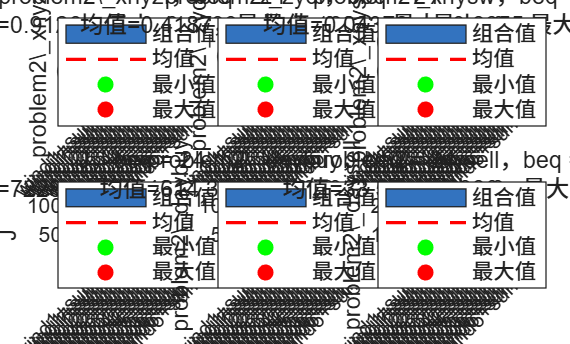

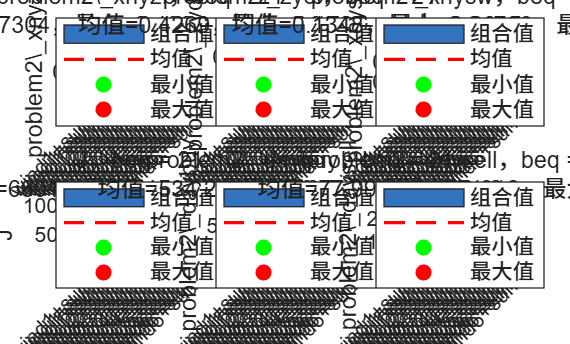

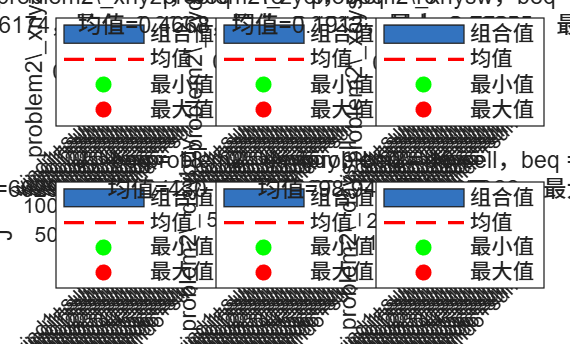

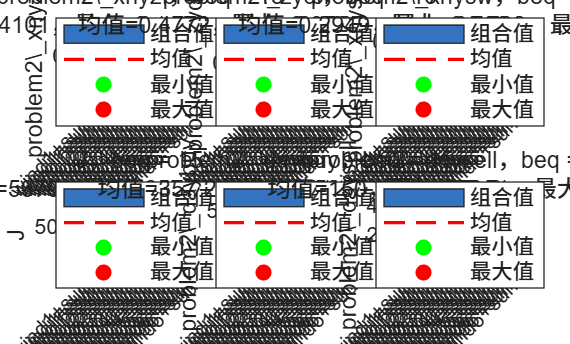

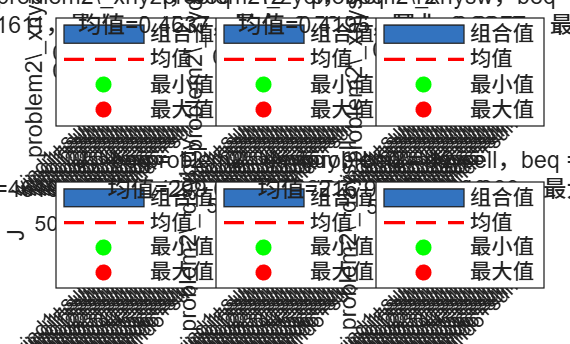


plotProblem2Distributions(problem2_results, beq_values);


function metrics = calcProblem2Metrics(t, classicload, wind, sun, fenshijijia )
                                     
    t = t(:);
    classicload = classicload(:);
    wind = wind(:);
    sun = sun(:);
    fenshijijia = fenshijijia(:);

    metrics.nh3load = t*20.75*2;
    metrics.load = classicload*6 + metrics.nh3load;
    metrics.generate = wind*40 + sun*64;
    metrics.buy = metrics.load - metrics.generate;
    metrics.sell = metrics.buy;
    metrics.buy(metrics.buy<0) = 0;
    metrics.sell(metrics.sell>0) = 0;
    metrics.buycost = sum(metrics.buy .* fenshijijia);
    metrics.dayload = sum(metrics.load);
    metrics.daygenerate = sum(metrics.generate);
    metrics.daybuy = sum(metrics.buy);
    metrics.daysell = abs(sum(metrics.sell));

    % 保持原文件的指标计算方式

    metrics.xnyzf = (metrics.dayload-metrics.daysell-metrics.daybuy)/metrics.daygenerate;
    metrics.zydl = (metrics.daygenerate-metrics.daysell)/metrics.dayload;
    metrics.xnysw = metrics.daysell/metrics.daygenerate;
end


function plotProblem2Distributions(problem2_results, beq_values)
    metric_fields = {'xnyzf', 'zydl', 'xnysw', 'J_min', 'daybuy', 'daysell'};
    metric_names = {'problem2\_xnyzf', 'problem2\_zydl', 'problem2\_xnysw', ...
                    'J', 'problem2\_daybuy', 'problem2\_daysell'};

    for beq_idx = 1:numel(beq_values)
        beq = beq_values(beq_idx);
        beq_mask = [problem2_results.beq] == beq;
        beq_results = problem2_results(beq_mask);

        if isempty(beq_results)
            warning('beq = %g 没有可绘制的结果。', beq);
            continue;
        end

        sort_keys = [[beq_results.wind_idx]', [beq_results.sun_idx]'];
        [~, order] = sortrows(sort_keys, [1 2]);
        beq_results = beq_results(order);

        combo_labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), ...
                                beq_results, 'UniformOutput', false);

        figure('Name', sprintf('beq=%g 下 24 种 wind/sun 组合指标分布', beq), ...
               'Color', 'w');

        for metric_idx = 1:numel(metric_fields)
            metric_field = metric_fields{metric_idx};
            metric_name = metric_names{metric_idx};
            values = arrayfun(@(r) r.(metric_field), beq_results);

            subplot(2, 3, metric_idx);
            bar(values, 'FaceColor', [0.2 0.45 0.75]);
            grid on;
            hold on;

            valid_values = values(~isnan(values));
            mean_value = mean(valid_values);
            min_value = min(valid_values);
            max_value = max(valid_values);
            [~, min_idx] = min(values);
            [~, max_idx] = max(values);

            plot(xlim, [mean_value mean_value], 'r--', 'LineWidth', 1.2);
            scatter(min_idx, min_value, 45, 'g', 'filled');
            scatter(max_idx, max_value, 45, 'r', 'filled');

            title({sprintf('%s，beq = %g', metric_name, beq), ...
                   sprintf('均值=%.4g，最小=%.4g，最大=%.4g', ...
                           mean_value, min_value, max_value)}, ...
                  'Interpreter', 'none');
            xlabel('wind + sun 组合');
            ylabel(metric_name, 'Interpreter', 'none');
            set(gca, 'XTick', 1:numel(combo_labels), ...
                     'XTickLabel', combo_labels, ...
                     'XTickLabelRotation', 45);
            xlim([0.5, numel(combo_labels) + 0.5]);

            if min_value == max_value
                ylim([min_value - 0.5, max_value + 0.5]);
            end

            legend({'组合值', '均值', '最小值', '最大值'}, ...
                   'Location', 'best', 'FontSize', 8);
            hold off;
        end
    end
end

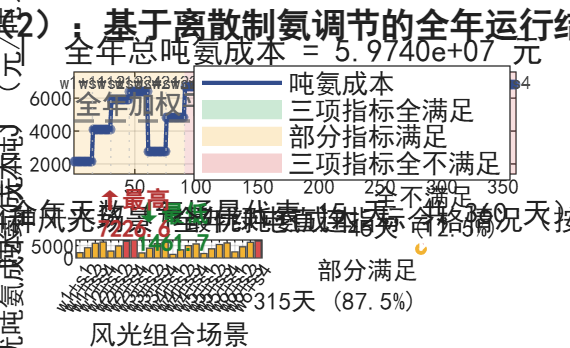

%% ========== 问题二(2) 全年吨氨成本分布曲线绘制 ==========
% 依赖：problem2_results（24种风光场景 × 5种产量 = 120条记录）
% 必须先跑过 24 场景的那段循环（含 wind_vectors / sun_vectors 的双层循环）

assert(exist('problem2_results','var')==1, 'problem2_results 不存在');

% 兼容性检查：必须有 24*5=120 条记录
n_records = numel(problem2_results);
if n_records ~= 120
    error(['problem2_results 当前有 %d 条记录，期望 120 条（24场景×5产量）。\n' ...
           '请先运行 24 种 wind+sun 组合的双层循环优化代码。'], n_records);
end

% 字段兼容：老版本可能没有 wind_idx/sun_idx，从 case_idx 反推
fns = fieldnames(problem2_results);
if ~ismember('wind_idx', fns)
    % case_idx 排列顺序：外层 wind 1..6，内层 sun 1..4，每个组合下 5 个 beq
    % 即第 k 条记录的 (wind_idx, sun_idx, beq_idx)：
    %   wind_idx = floor((k-1)/(4*5)) + 1
    %   sun_idx  = mod(floor((k-1)/5), 4) + 1
    for k = 1:n_records
        problem2_results(k).wind_idx = floor((k-1)/(4*5)) + 1;
        problem2_results(k).sun_idx  = mod(floor((k-1)/5), 4) + 1;
        problem2_results(k).wind_name = sprintf('wind%d', problem2_results(k).wind_idx);
        problem2_results(k).sun_name  = sprintf('sun%d',  problem2_results(k).sun_idx);
    end
    warning('problem2_results 中无 wind_idx 字段，已按 case_idx 顺序自动补齐。请核对场景顺序是否为 wind 外层、sun 内层。');
end

%% --- 1. 数据整理 ---
all_wind_idx = [problem2_results.wind_idx];
all_sun_idx  = [problem2_results.sun_idx];

n_wind = max(all_wind_idx);   % 6
n_sun  = max(all_sun_idx);    % 4
n_scen = n_wind * n_sun;      % 24
days_per_scen = 15;
n_days_year   = n_scen * days_per_scen;   % 360

best_J        = zeros(n_scen,1);
best_beq      = zeros(n_scen,1);
best_xnyzf    = zeros(n_scen,1);
best_zydl     = zeros(n_scen,1);
best_xnysw    = zeros(n_scen,1);
best_label    = strings(n_scen,1);
best_prod_ton = zeros(n_scen,1);

beq_to_ton = @(b) b * 1.5 * 2;   % 日产氨吨数 = sum(t)*1.5*2

scen_id = 0;
for wi = 1:n_wind
    for si = 1:n_sun
        scen_id = scen_id + 1;
        mask = (all_wind_idx==wi) & (all_sun_idx==si);
        sub = problem2_results(mask);
        if isempty(sub)
            error('场景 wind%d+sun%d 在 problem2_results 中找不到记录', wi, si);
        end
        [J_min_val, k] = min([sub.J_min]);
        best_J(scen_id)     = J_min_val;
        best_beq(scen_id)   = sub(k).beq;
        best_xnyzf(scen_id) = sub(k).xnyzf;
        best_zydl(scen_id)  = sub(k).zydl;
        best_xnysw(scen_id) = sub(k).xnysw;
        best_label(scen_id) = sprintf('w%d+s%d', wi, si);
        best_prod_ton(scen_id) = beq_to_ton(sub(k).beq);
    end
end

% 绿电指标合格性
ok_xnyzf = best_xnyzf > 0.60;
ok_zydl  = best_zydl  > 0.30;
ok_xnysw = best_xnysw < 0.20;
ok_all   = ok_xnyzf & ok_zydl & ok_xnysw;
n_pass_each = [ok_xnyzf, ok_zydl, ok_xnysw];
n_pass      = sum(n_pass_each, 2);   % 每个场景通过几项（0/1/2/3）
ok_part     = (n_pass>=1) & (n_pass<=2);
ok_none     = (n_pass==0);

n_full = sum(ok_all);  n_part = sum(ok_part);  n_none = sum(ok_none);

%% --- 2. 全年序列 ---
year_J     = repelem(best_J,        days_per_scen);
year_prod  = repelem(best_prod_ton, days_per_scen);

total_year_cost = sum(year_J .* year_prod);
total_year_ton  = sum(year_prod);
avg_year_cost   = total_year_cost / total_year_ton;

%% --- 3. 绘图 ---
fig = figure('Name','问题二(2) 全年吨氨成本分布','Color','w',...
             'Position',[100 100 1280 780]);
set(fig,'DefaultAxesFontName','SimHei','DefaultTextFontName','SimHei');

c_full = [0.20 0.65 0.35];
c_part = [0.95 0.70 0.20];
c_none = [0.85 0.30 0.30];
c_line = [0.20 0.30 0.55];

% ---- 子图1：全年吨氨成本分布曲线 ----
ax1 = subplot(2,2,[1 2]); hold(ax1,'on'); grid(ax1,'on'); box(ax1,'on');

x = 1:n_days_year;
y_lo = min(year_J)*0.95;  y_hi = max(year_J)*1.05;

for s = 1:n_scen
    x_start = (s-1)*days_per_scen + 0.5;
    x_end   =  s   *days_per_scen + 0.5;
    if ok_all(s),       fc = c_full;
    elseif ok_part(s),  fc = c_part;
    else,               fc = c_none;
    end
    patch(ax1,[x_start x_end x_end x_start], ...
          [y_lo y_lo y_hi y_hi], ...
          fc,'FaceAlpha',0.18,'EdgeColor','none','HandleVisibility','off');
end

plot(ax1, x, year_J, '-', 'Color', c_line, 'LineWidth', 1.6);
scatter(ax1, x, year_J, 14, c_line, 'filled', 'MarkerFaceAlpha', 0.6, 'HandleVisibility','off');

yline(ax1, avg_year_cost, '--', sprintf('全年加权平均 = %.2f 元/吨', avg_year_cost), ...
      'Color',[0.4 0.4 0.4], 'LineWidth', 1.3, ...
      'LabelHorizontalAlignment','left','FontSize', 10);

for s = 1:n_scen-1
    xline(ax1, s*days_per_scen+0.5, ':', 'Color',[0.75 0.75 0.75], 'HandleVisibility','off');
end

% 在每个场景顶部标注组合名
for s = 1:n_scen
    text(ax1, (s-0.5)*days_per_scen+0.5, y_hi*0.995, best_label(s), ...
        'HorizontalAlignment','center','VerticalAlignment','top', ...
        'FontSize',7,'Color',[0.3 0.3 0.3]);
end

xlabel(ax1,'全年天数（每场景代表 15 天，共 360 天）','FontSize',11);
ylabel(ax1,'吨氨成本 J （元/吨）','FontSize',11);
title(ax1, sprintf('园区全年吨氨成本分布曲线  |  全年总吨氨成本 = %.4e 元  |  全年总产量 = %.1f 吨', ...
       total_year_cost, total_year_ton), 'FontSize',12);
xlim(ax1,[0.5 n_days_year+0.5]);
ylim(ax1,[y_lo y_hi]);

h1 = patch(nan,nan,c_full,'FaceAlpha',0.25,'EdgeColor','none');
h2 = patch(nan,nan,c_part,'FaceAlpha',0.25,'EdgeColor','none');
h3 = patch(nan,nan,c_none,'FaceAlpha',0.25,'EdgeColor','none');
h4 = plot(ax1,nan,nan,'-','Color',c_line,'LineWidth',1.6);
legend(ax1,[h4 h1 h2 h3], ...
       {'吨氨成本','三项指标全满足','部分指标满足','三项指标全不满足'}, ...
       'Location','best','FontSize',10);

% ---- 子图2：24场景最优吨氨成本柱状图 ----
ax2 = subplot(2,2,3); hold(ax2,'on'); grid(ax2,'on'); box(ax2,'on');
bar_colors = repmat(c_part,n_scen,1);
bar_colors(ok_all,:)  = repmat(c_full, n_full, 1);
bar_colors(ok_none,:) = repmat(c_none, n_none, 1);

b = bar(ax2, 1:n_scen, best_J, 'FaceColor','flat','EdgeColor',[0.3 0.3 0.3]);
b.CData = bar_colors;

[J_lo, i_lo] = min(best_J);
[J_hi, i_hi] = max(best_J);
text(ax2, i_lo, J_lo, sprintf('↓最低\n%.1f', J_lo), ...
     'HorizontalAlignment','center','VerticalAlignment','bottom',...
     'FontSize',9,'Color',[0.1 0.5 0.2],'FontWeight','bold');
text(ax2, i_hi, J_hi, sprintf('↑最高\n%.1f', J_hi), ...
     'HorizontalAlignment','center','VerticalAlignment','bottom',...
     'FontSize',9,'Color',[0.7 0.2 0.2],'FontWeight','bold');

set(ax2,'XTick',1:n_scen,'XTickLabel',cellstr(best_label),...
    'XTickLabelRotation',55,'FontSize',8);
xlabel(ax2,'风光组合场景','FontSize',10);
ylabel(ax2,'最优吨氨成本（元/吨）','FontSize',10);
title(ax2,'24种风光场景下最优吨氨成本','FontSize',11);
xlim(ax2,[0.5 n_scen+0.5]);

% ---- 子图3：合格情况饼图 ----
ax3 = subplot(2,2,4);
days_full = n_full * days_per_scen;
days_part = n_part * days_per_scen;
days_none = n_none * days_per_scen;
pie_data   = [days_full, days_part, days_none];
pie_labels = {sprintf('全满足\n%d天 (%.1f%%)', days_full, days_full/n_days_year*100), ...
              sprintf('部分满足\n%d天 (%.1f%%)', days_part, days_part/n_days_year*100), ...
              sprintf('全不满足\n%d天 (%.1f%%)', days_none, days_none/n_days_year*100)};
valid = pie_data > 0;
colors_pie = [c_full; c_part; c_none];
colors_pie = colors_pie(valid,:);
ph = pie(ax3, pie_data(valid), pie_labels(valid));
patches_idx = 1;
for kk = 1:numel(ph)
    if isa(ph(kk),'matlab.graphics.primitive.Patch')
        ph(kk).FaceColor = colors_pie(patches_idx,:);
        ph(kk).EdgeColor = 'w';
        ph(kk).LineWidth = 1.2;
        patches_idx = patches_idx + 1;
    elseif isa(ph(kk),'matlab.graphics.primitive.Text')
        ph(kk).FontSize = 9.5;
        ph(kk).FontName = 'SimHei';
    end
end
title(ax3,'全年绿电直连指标合格情况（按天数）','FontSize',11);

sgtitle('问题二（2）：基于离散制氨调节的全年运行结果分析','FontSize',13,'FontWeight','bold');


%% --- 4. 控制台汇总 ---
fprintf('\n========== 问题二(2) 全年统计汇总 ==========\n');


========== 问题二(2) 全年统计汇总 ==========


fprintf('全年天数         : %d 天（24场景 × 15天）\n', n_days_year);

全年天数         : 360 天（24场景 × 15天）


fprintf('全年总产氨量     : %.2f 吨\n', total_year_ton);

全年总产氨量     : 12960.00 吨


fprintf('全年总吨氨成本   : %.4e 元\n', total_year_cost);

全年总吨氨成本   : 5.9740e+07 元


fprintf('全年加权平均成本 : %.2f 元/吨\n', avg_year_cost);

全年加权平均成本 : 4609.56 元/吨


fprintf('最低吨氨成本场景 : %s ，J = %.2f 元/吨\n', best_label(i_lo), J_lo);

最低吨氨成本场景 : w4+s1 ，J = 1461.72 元/吨


fprintf('最高吨氨成本场景 : %s ，J = %.2f 元/吨\n', best_label(i_hi), J_hi);

最高吨氨成本场景 : w2+s4 ，J = 7226.57 元/吨


fprintf('绿电指标 全满足  : %d 场景 / %d 天 (%.1f%%)\n', n_full, days_full, days_full/n_days_year*100);

绿电指标 全满足  : 0 场景 / 0 天 (0.0%)


fprintf('绿电指标 部分满足: %d 场景 / %d 天 (%.1f%%)\n', n_part, days_part, days_part/n_days_year*100);

绿电指标 部分满足: 21 场景 / 315 天 (87.5%)


fprintf('绿电指标 全不满足: %d 场景 / %d 天 (%.1f%%)\n', n_none, days_none, days_none/n_days_year*100);

绿电指标 全不满足: 3 场景 / 45 天 (12.5%)



T = table((1:n_scen)', best_label, best_prod_ton, best_beq, best_J, ...
          best_xnyzf, best_zydl, best_xnysw, ok_all, ...
    'VariableNames', {'场景','风光组合','日产氨_吨','sum_t','吨氨成本',...
                      '自发自用比','绿电占比','上网比','三项全合格'});
disp(T);

    场景    风光组合    日产氨_吨    sum_t    吨氨成本    自发自用比    绿电占比     上网比     三项全合格
    ____    _______    ________    _____    _______    _________    _______    _______    _________

      1     "w1+s1"       36        12      2147.1      -0.14538     0.5826    0.57269      false  
      2     "w1+s2"       36        12      4118.6       0.17733    0.53017    0.41134      false  
      3     "w1+s3"       36        12      5923.5       0.22658     0.3704    0.38671      false  
      4     "w1+s4"       36        12      6396.5       0.40873    0.34392    0.29563      false  
      5     "w2+s1"       36        12      2769.7      -0.10317    0.52882    0.55158      false  
      6     "w2+s2"       36        12      4852.1       0.25607    0.45001    0.37197      false  
      7     "w2+s3"       36        12      6687.3       0.20644    0.25327    0.39678      false  
      8     "w2+s4"       36        12      7226.6       0.52461    0.23187    0.23769      false  
      9     "w3+s1"    